close all; clear all;

load("lenag_SD.mat");

**Loading and showing picture**

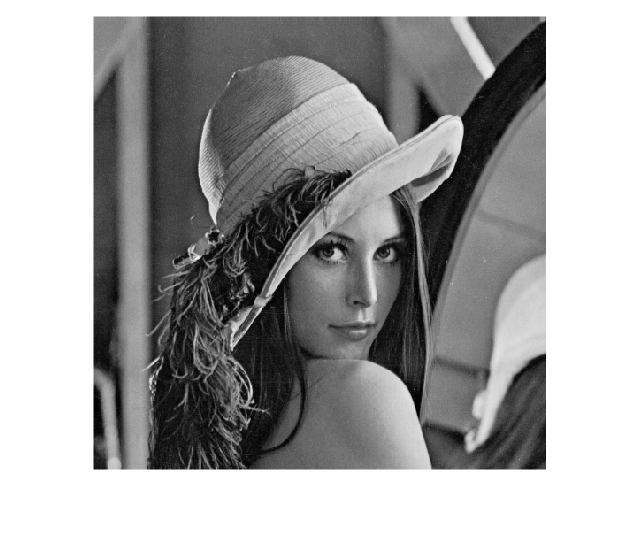

imshow(lenag, []);

**2D-FFT**

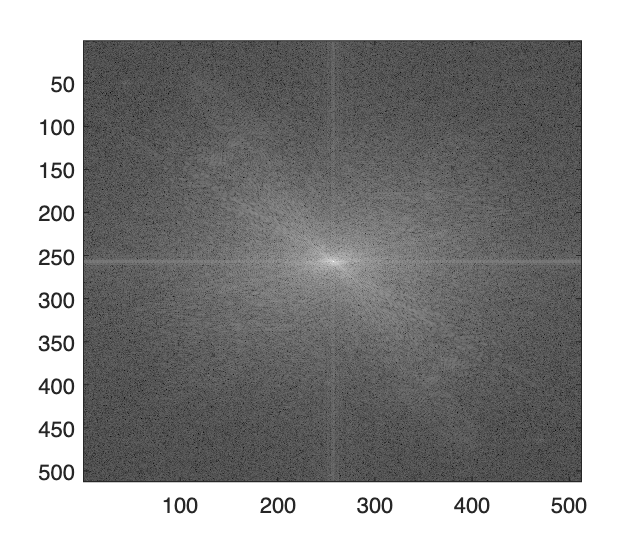

FFT_Y = fft2(lenag);

n = max(FFT_Y, [], "all");

FFT_Y_db = log(abs(fftshift(FFT_Y/n)));

imagesc(FFT_Y_db);
colormap("gray");


% imshow(FFT_Y_db, []);

This transform does not provide any useful information

**2D-DCT**

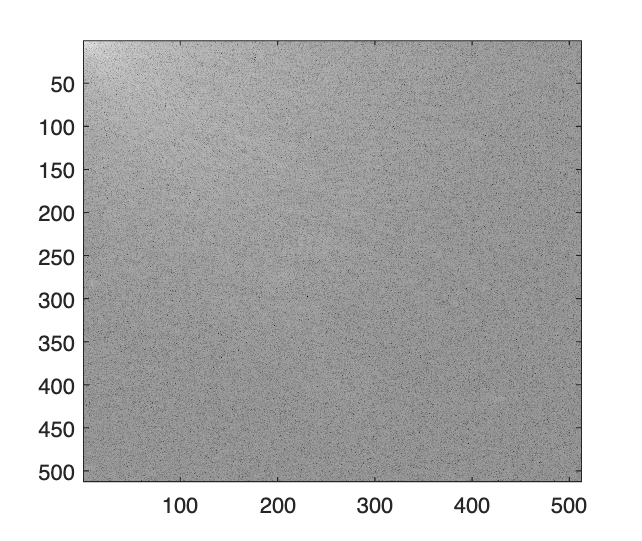

DCT_Y = dct2(lenag);

% For normalizing
m = max(DCT_Y, [], "all");

DCT_Y_db = log(abs(DCT_Y)/m);

imagesc(DCT_Y_db);

% imshow(DCT_Y_db, []);

**Choosing an 8x8 block and taking the 2D-DCT**

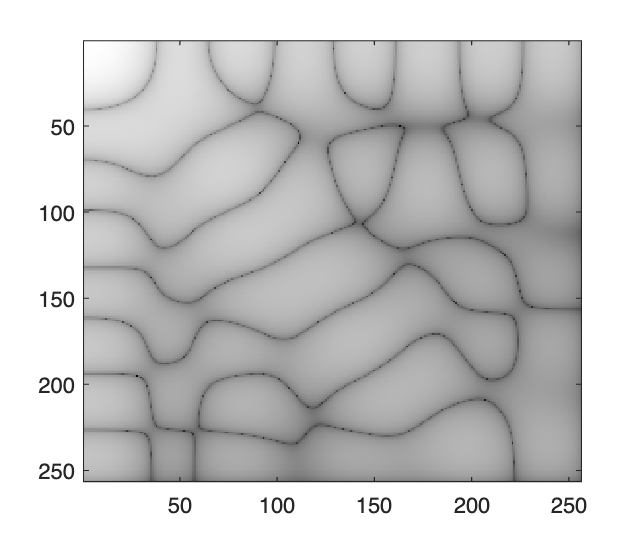

i = 250; j = 250;
block = lenag(i:i+7, j:j+7);

DCT_block = dct2(block, 256, 256);
DCT_block_db = log(abs(DCT_block)/m);

% imshow(DCT_block_db, []);
imagesc(DCT_block_db);